# Input basic information for file names

clc;
clear;

experimentNumber = 'test';
subject = '1(Li)';
excelDataFilePath = "D:\OneDrive\Desktop\Graduate Project\log\20241005\Han\tide_MAX86176_20241005_132957_PPG.xlsx"

excelDataFilePath = "D:\OneDrive\Desktop\Graduate Project\log\20241005\Han\tide_MAX86176_20241005_132957_PPG.xlsx"

PPGTitle="LED1\_PPG data from experiment" + experimentNumber + " for subject" +subject; 
accTitle="Accelerometer Data from experiment"+experimentNumber+" for subject"+subject;
finalTitle = "Accelerometer and PPG Data from experiment"+experimentNumber+" for subjet"+subject ;

exportPath = "./Subject" + subject + "/experiment" +experimentNumber;

if ~exist(exportPath,'dir')
    mkdir(exportPath)
end

# Read the Excel file

data = readtable(excelDataFilePath);

# Preprocessing data

% Replace the colon before milliseconds with a period

% Get the number of timestamps
num_timestamps = length(data.Timestamp_Day_Month_YearHour_Minute_Second_Milisecond_);

% Initialize the modified timestamp column
data.Timestamp_modified = cell(num_timestamps, 1);

for i = 1:num_timestamps
    timestamp_str = data.Timestamp_Day_Month_YearHour_Minute_Second_Milisecond_{i};
    
    % using regular expression to match second and millisecond parts
    tokens = regexp(timestamp_str, '(\d{2}):(\d{1,3})$', 'tokens');
    if ~isempty(tokens)
        seconds_part = tokens{1}{1};
        milliseconds_part = tokens{1}{2};
        % append the millisecond part to 3 digits
        milliseconds_padded = sprintf('%03d', str2double(milliseconds_part));
        % replace colon with dot
        timestamp_modified = regexprep(timestamp_str, '(\d{2}):(\d{1,3})$', [seconds_part '.' milliseconds_padded]);
        data.Timestamp_modified{i} = timestamp_modified;
    else
        % if the timestamp does not match，record warning information
        data.Timestamp_modified{i} = timestamp_str;
        warning('format of timestamp does not match，cannot parse：%s', timestamp_str);
    end
end

% Parse the appended timestamps to datetime object
data.Time_in_datetime = datetime(data.Timestamp_modified, 'InputFormat', 'dd.MM.yyyy HH:mm:ss.SSS');
elapsed_time = seconds(data.Time_in_datetime - data.Time_in_datetime(1));

# Plot PPG data

## Use sliding windows

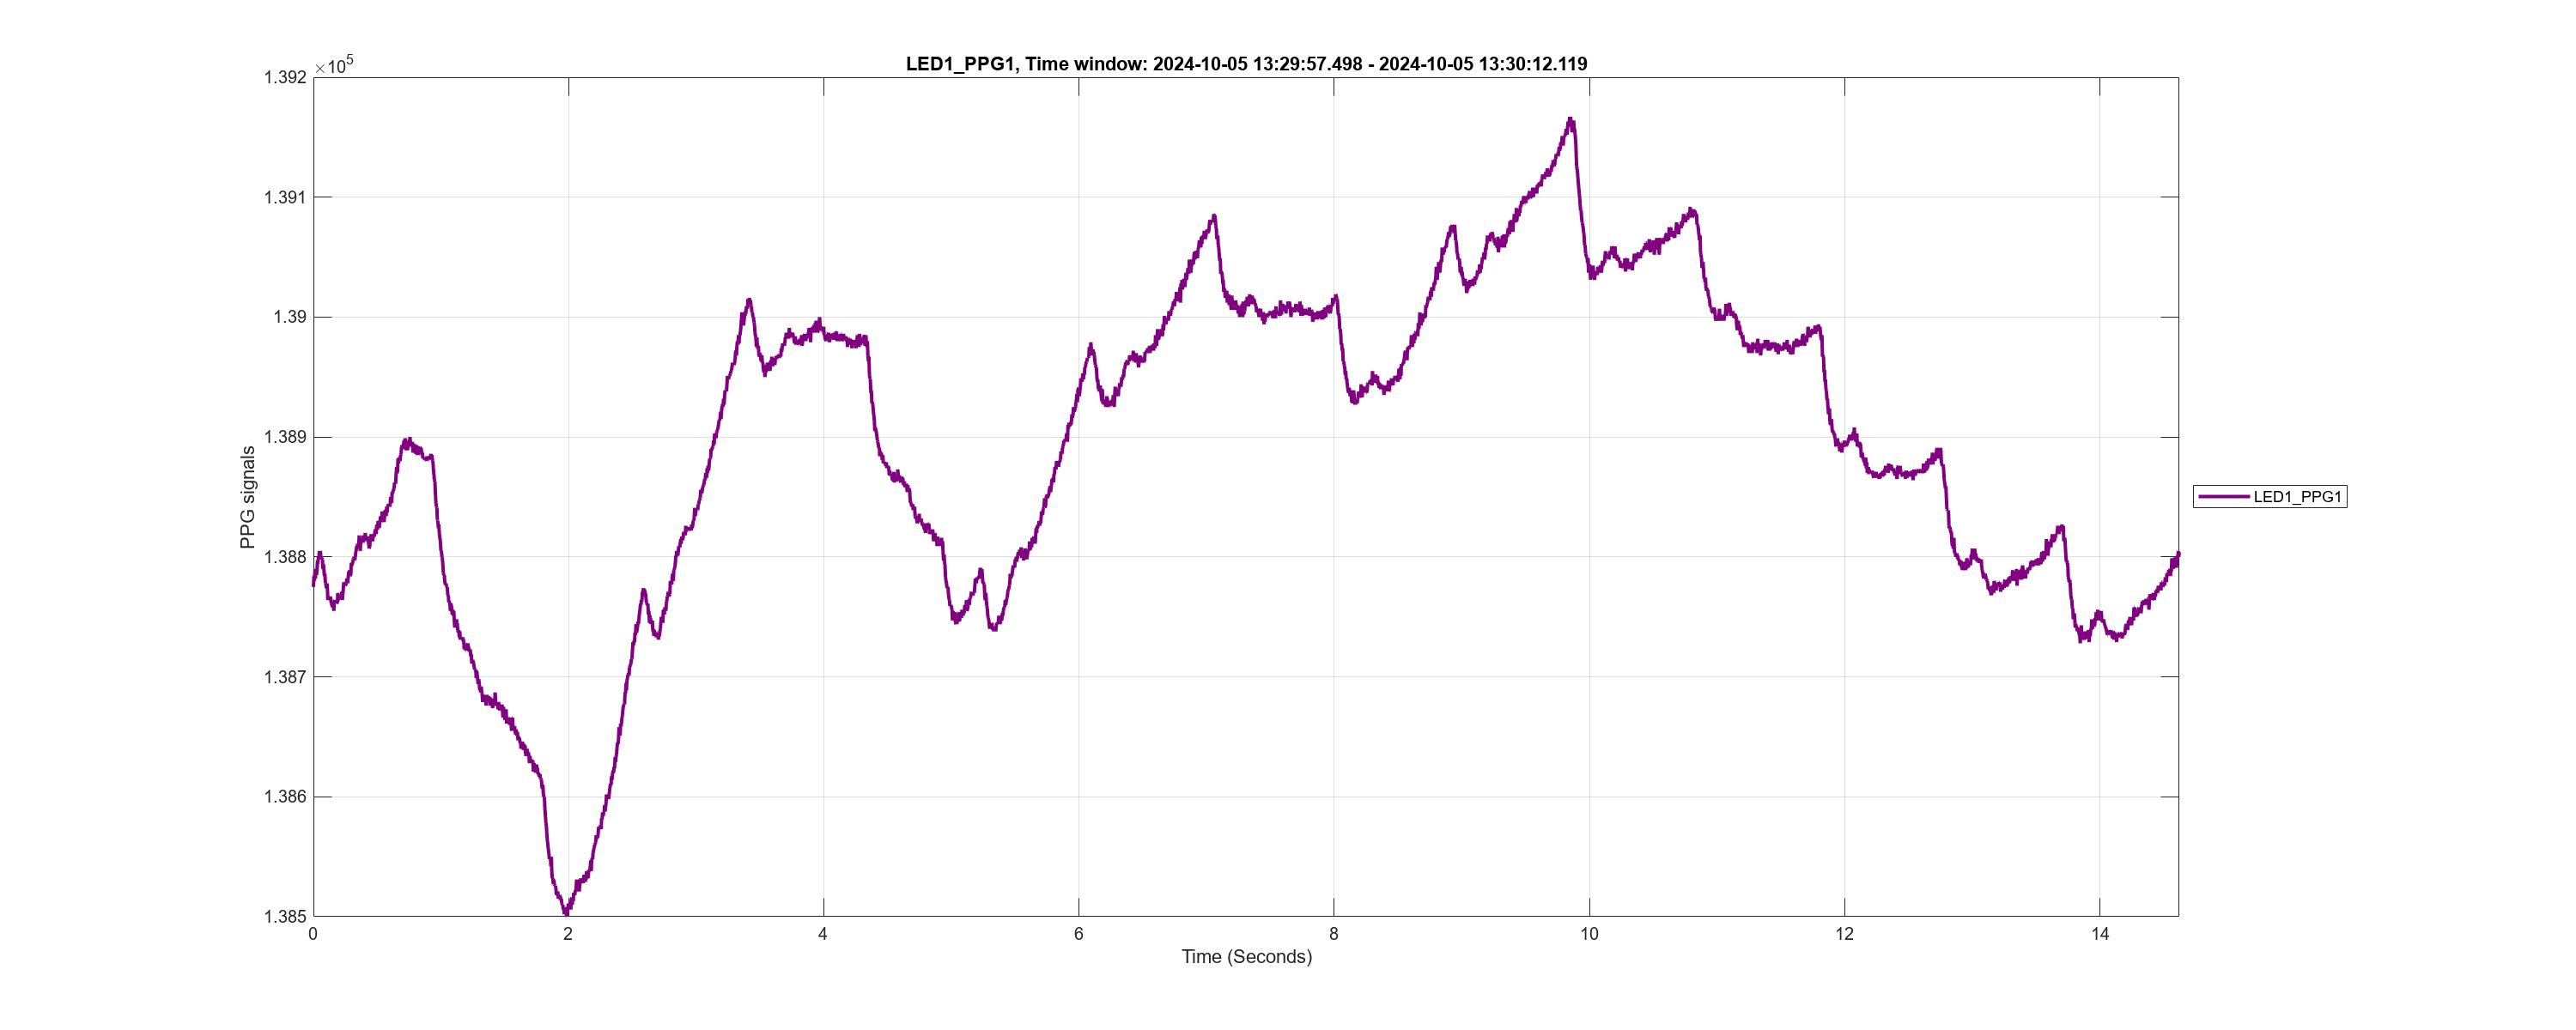

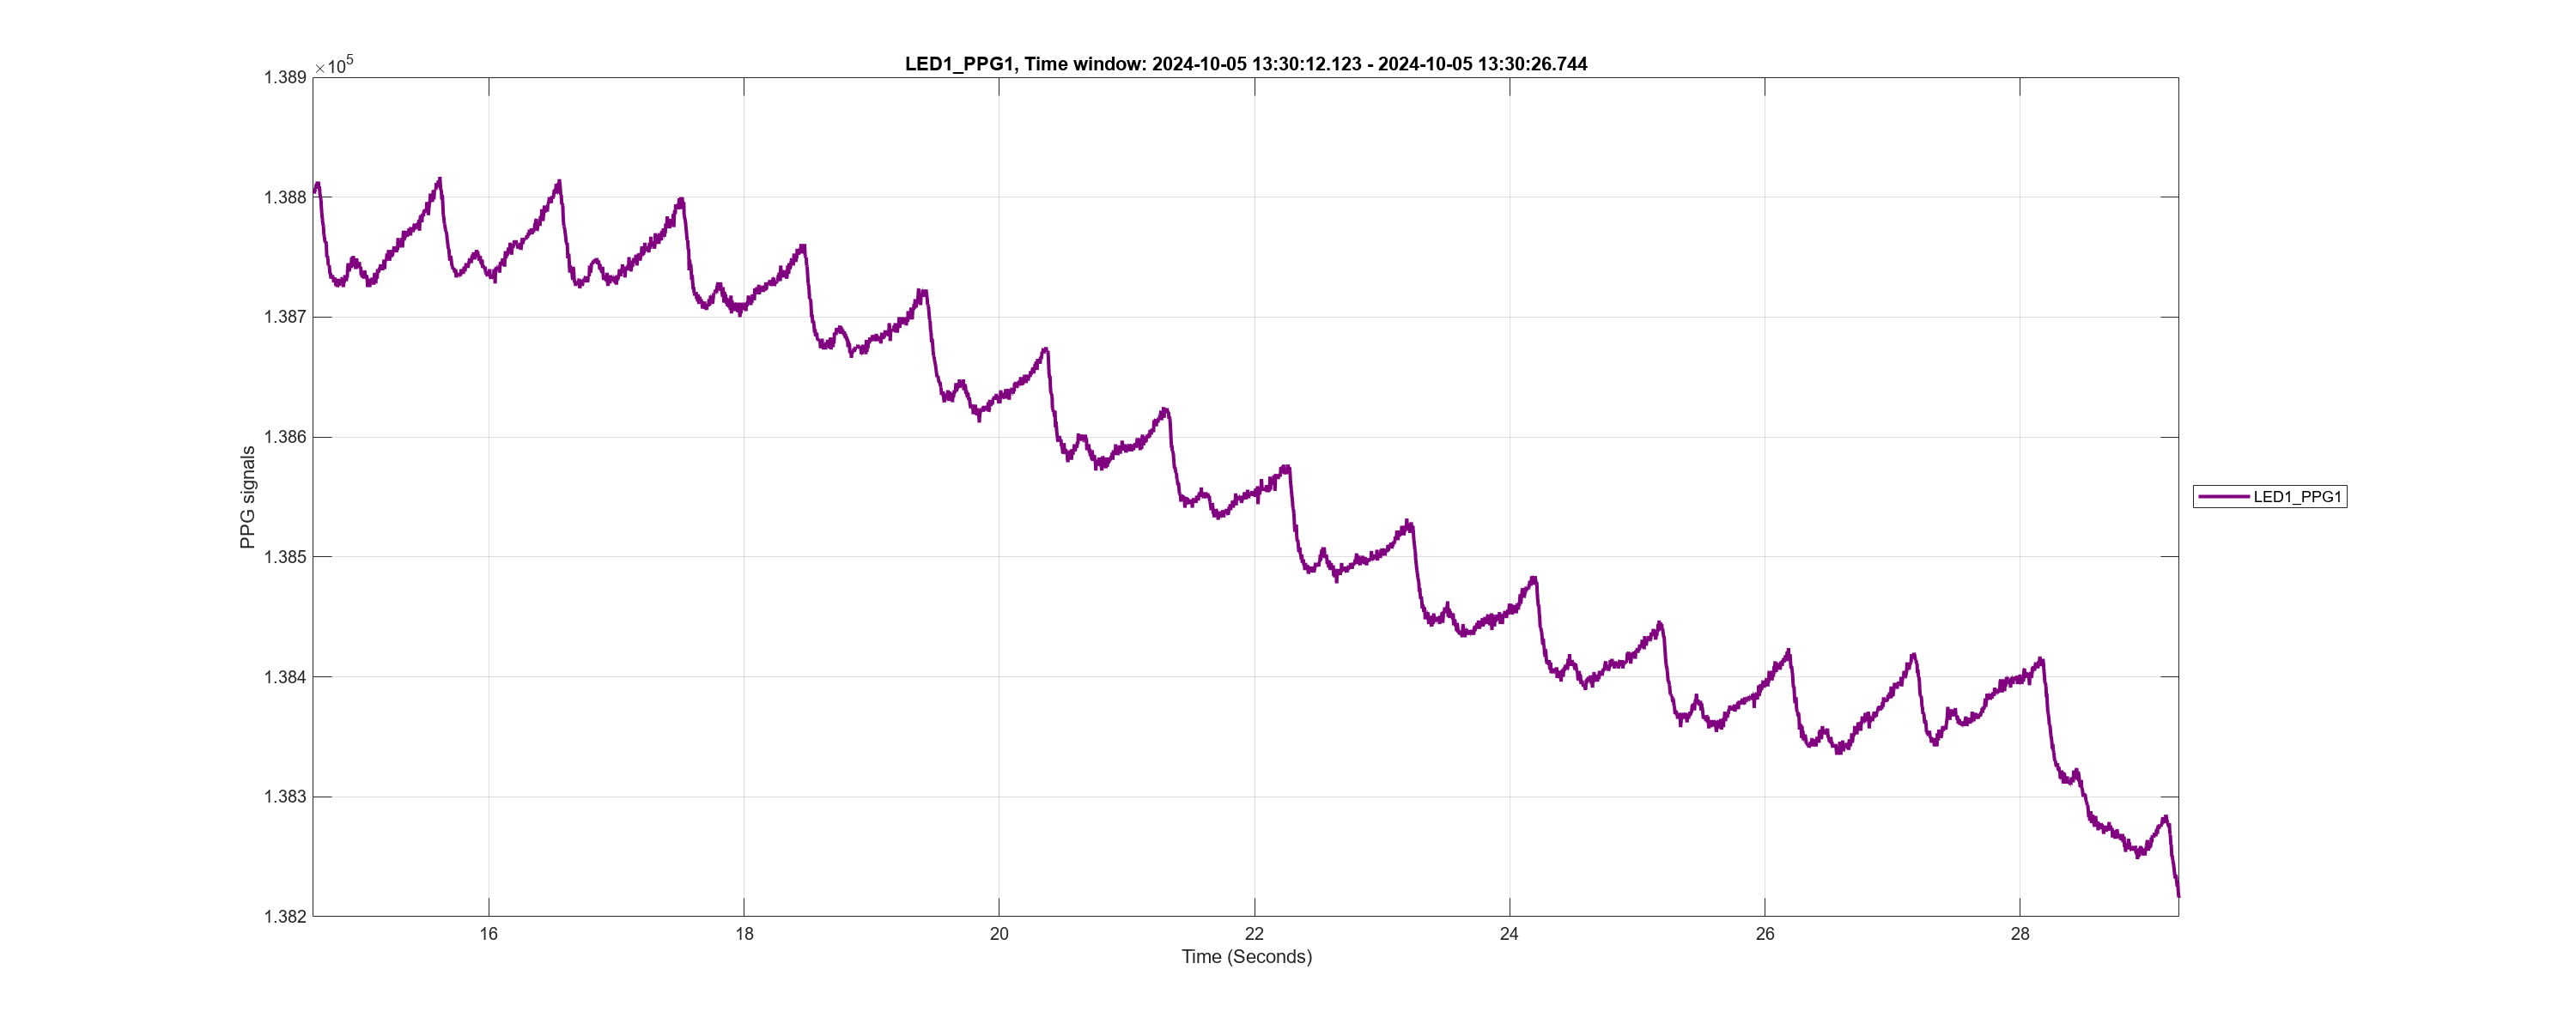

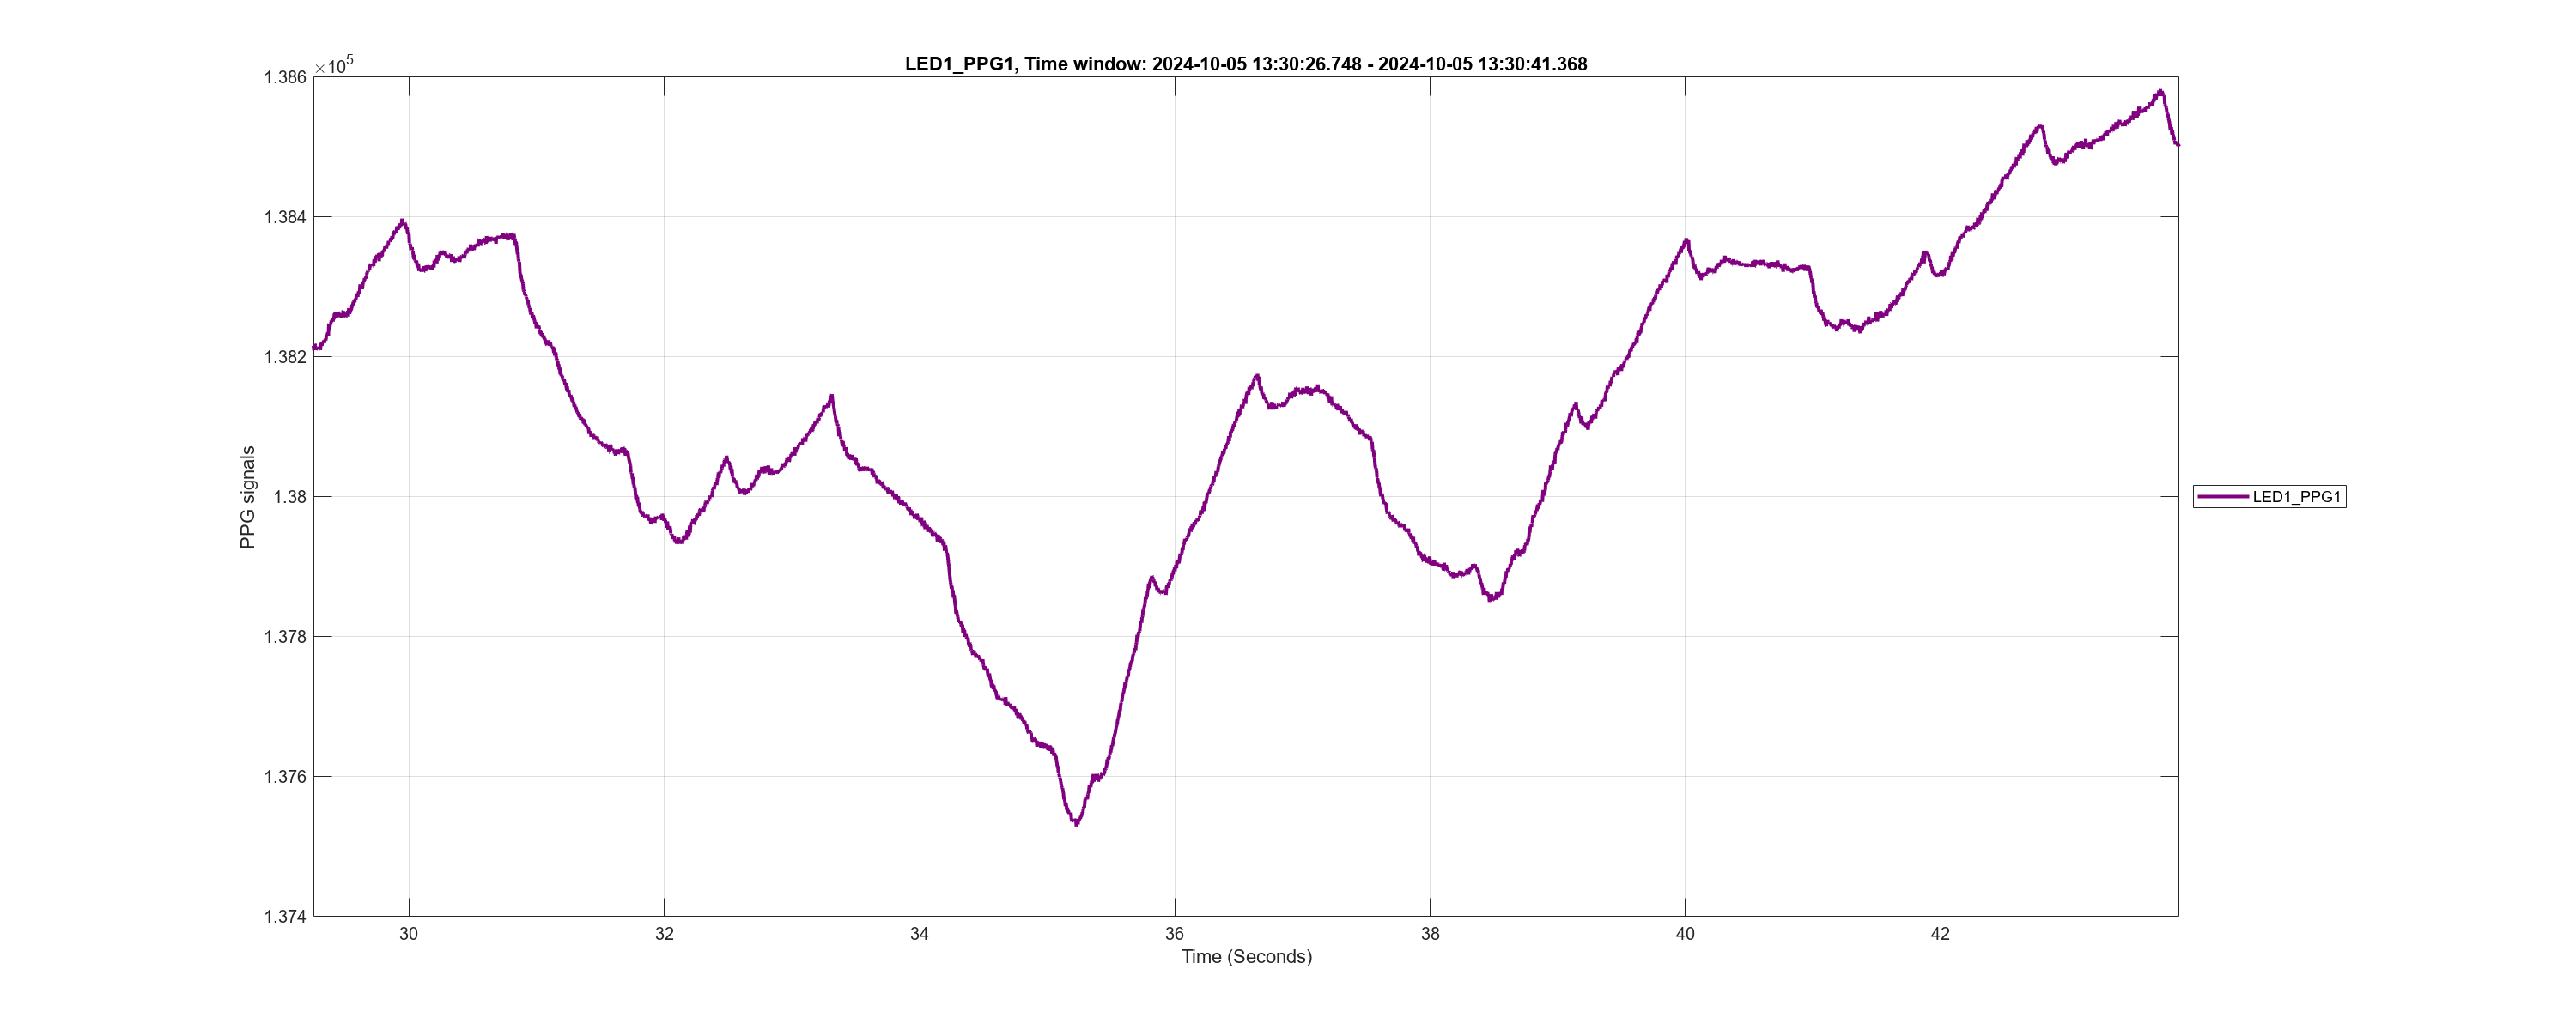

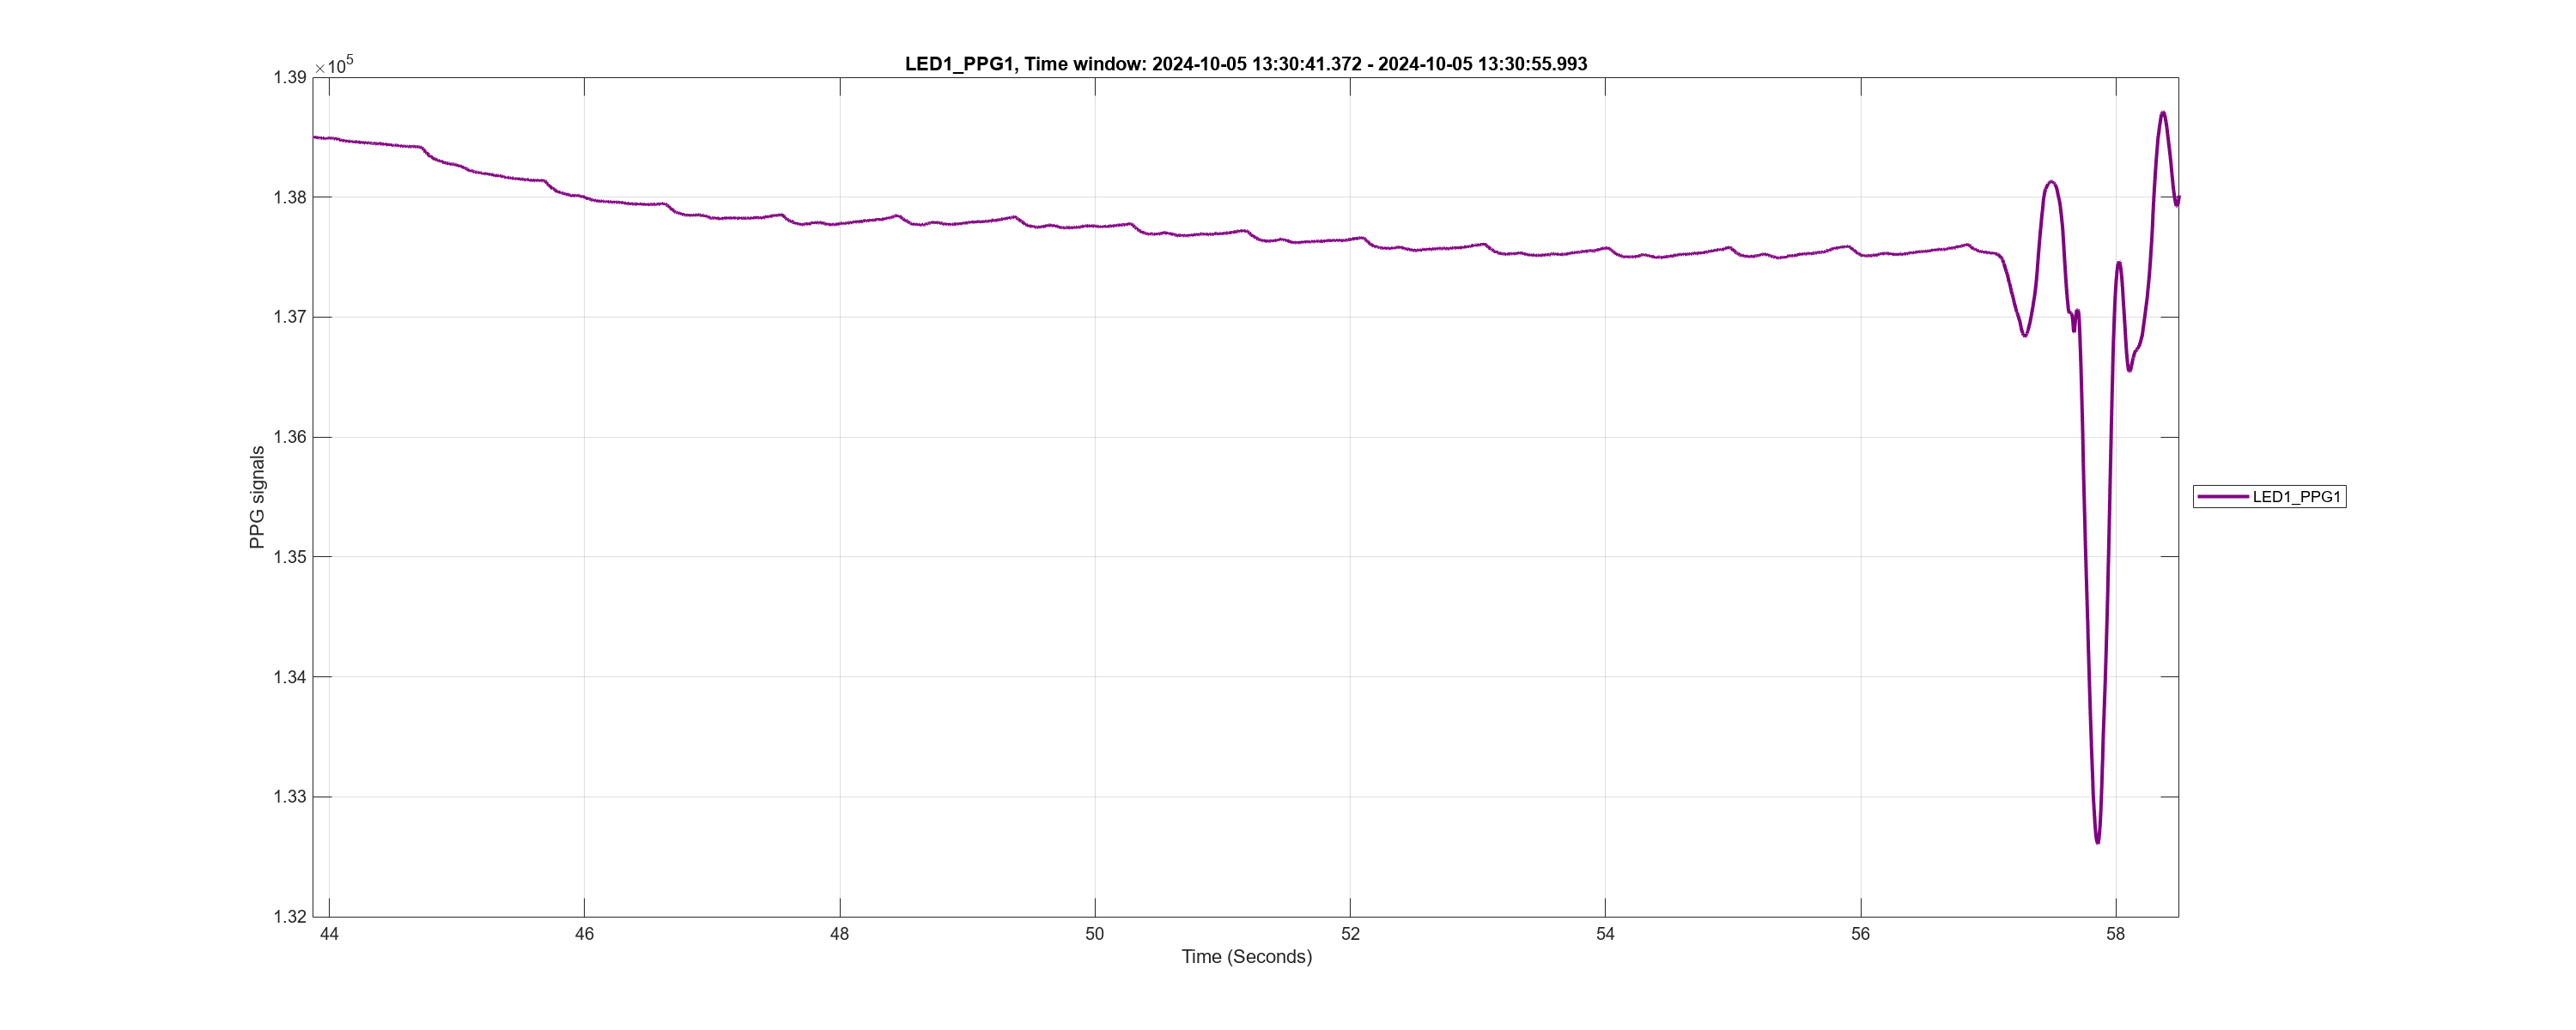

fs = 250;
window_size = 15 * fs;
step_size = window_size;
num_samples = length(data.LED1_PPG1);
time = elapsed_time; % Use datetime timestamps

for i = 1:step_size:(num_samples - window_size + 1)
    % Get data for the current window
    window_data = data.LED1_PPG1(i:i + window_size - 1);
    window_time = time(i:i + window_size - 1);

    % Plot the data
    figure;
    set(gcf, 'Position', [100, 100, 2000, 800]);
    plot(window_time, window_data, 'Color','#800080','LineWidth', 2 , 'DisplayName', 'LED1\_PPG1');
    xlabel('Time (Seconds)');
    ylabel('PPG signals');
     % 计算窗口的起始和结束时间的 datetime 对象
    time_start_datetime = data.Time_in_datetime(1) + seconds(window_time(1));
    time_end_datetime = data.Time_in_datetime(1) + seconds(window_time(end));
    
    % 在标题中使用正确的时间格式
    title(['LED1\_PPG1, Time window: ', datestr(time_start_datetime, 'yyyy-mm-dd HH:MM:SS.FFF'), ' - ', datestr(time_end_datetime, 'yyyy-mm-dd HH:MM:SS.FFF')]);
    % title(['LED1\_PPG1, Time window: ', datestr(window_time(1)), ' - ', datestr(window_time(end))]);
    xlim([window_time(1), window_time(end)]);
    grid on;
    legend('Location', 'eastoutside');

  
  
    % Prepare filename-friendly timestamps
    filename_start = datestr(time_start_datetime, 'yyyy-mm-dd_HH-MM-SS-FFF');
    filename_end = datestr(time_end_datetime, 'yyyy-mm-dd_HH-MM-SS-FFF');

    % Export the figure
    exportgraphics(gcf, fullfile(exportPath, ['PPG_LED1_data_for_experiment_', experimentNumber, '_subject_', subject, '_window_', filename_start, '_to_', filename_end, '.png']), 'Resolution', 1000);

    % Close the figure
    close;
end

## LED1_PPG1

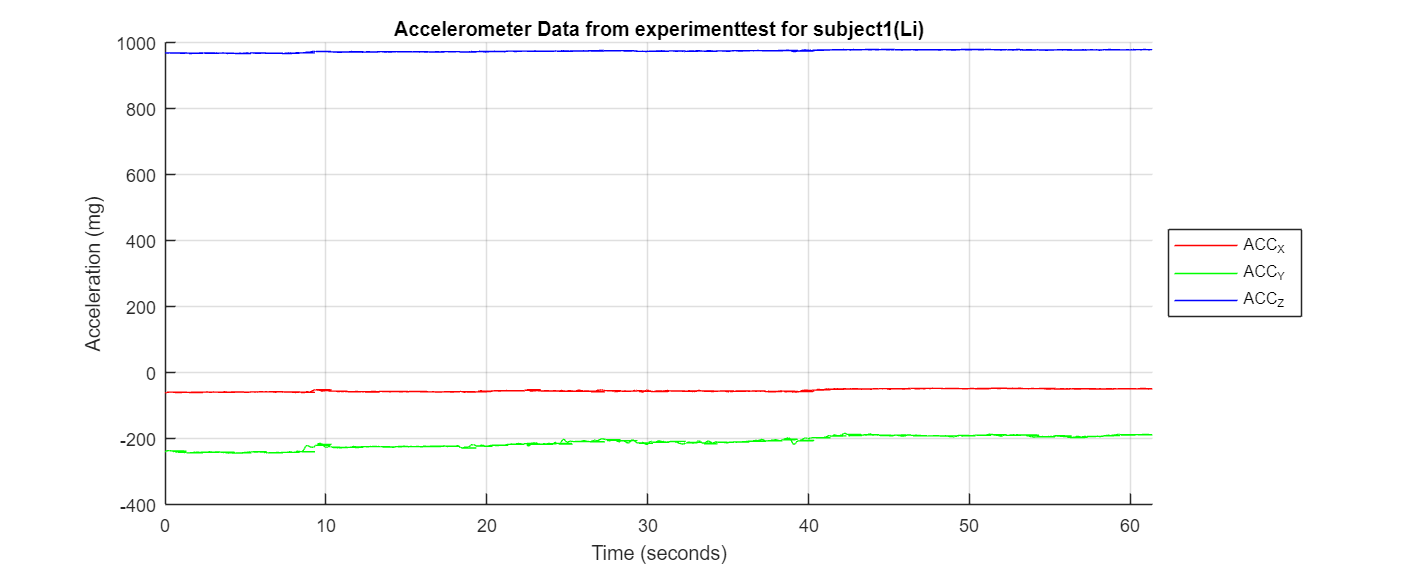

% plot LED1_PPG1
figure;
set(gcf, 'Position', [100, 100, 2000, 800]);  % add just window size [x, y, width, height]
plot(time, data.LED1_PPG1, 'Color','#800080','LineWidth', 2 , 'DisplayName', 'LED1\_PPG1');
xlabel('Time (seconds)');
ylabel('PPG signals');
title('LED1\_PPG1');

xlim([0 max(time)])

% ylim([min_value_LED1 - padding_LED1, max_value_LED1 + padding_LED1]); % set range of y-axis
grid on;
legend(Location="eastoutside");

% export
exportgraphics(gcf, exportPath+"\PPG_LED1_data_for_experiment"+ experimentNumber +"_subject"+subject+".png", 'Resolution', 1000);

## LED2_PPG1

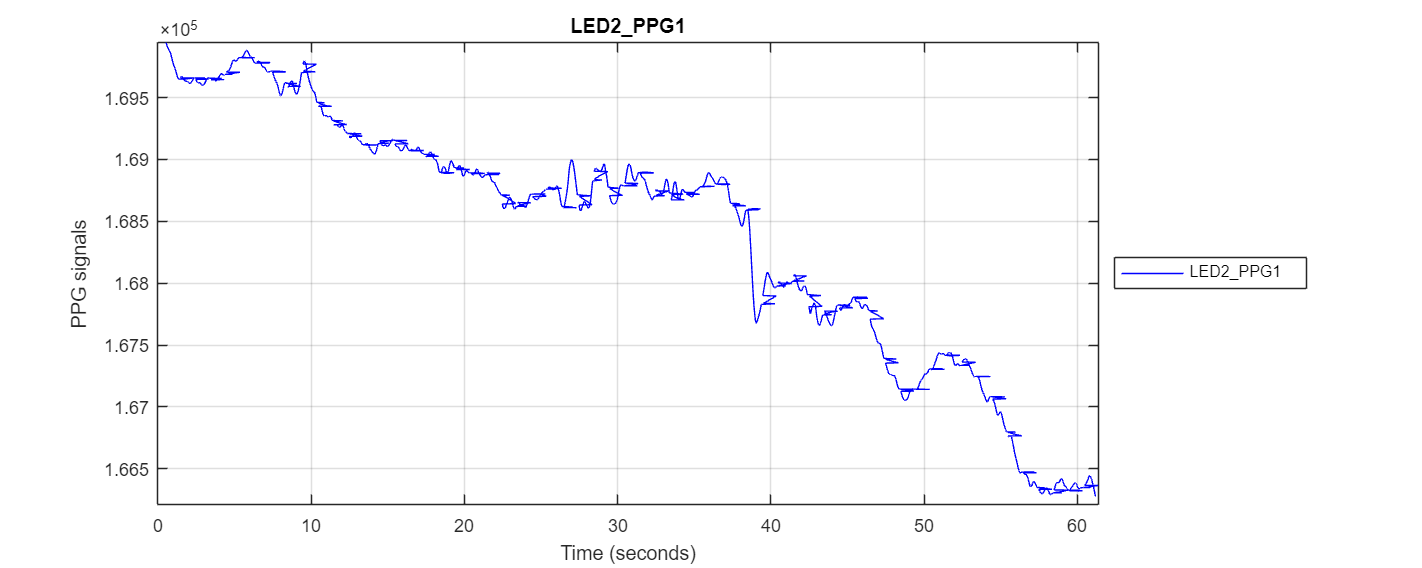

% plot LED2_PPG1
figure;
set(gcf, 'Position', [100, 100, 2000, 800]);  % 
plot(time, data.LED2_PPG1, 'Color','#FF0000','LineWidth', 2 , 'DisplayName', 'LED2\_PPG1');
xlabel('Time (seconds)');
ylabel('PPG signals');
title('LED2\_PPG1');
xlim([0 max(time)])
grid on;
legend(Location="eastoutside");

% export LED2 graph
exportgraphics(gcf, exportPath+"\PPG_LED2_data_for_experiment"+ experimentNumber +"_subject"+subject+".png", 'Resolution', 1000);

## LED3_PPG1

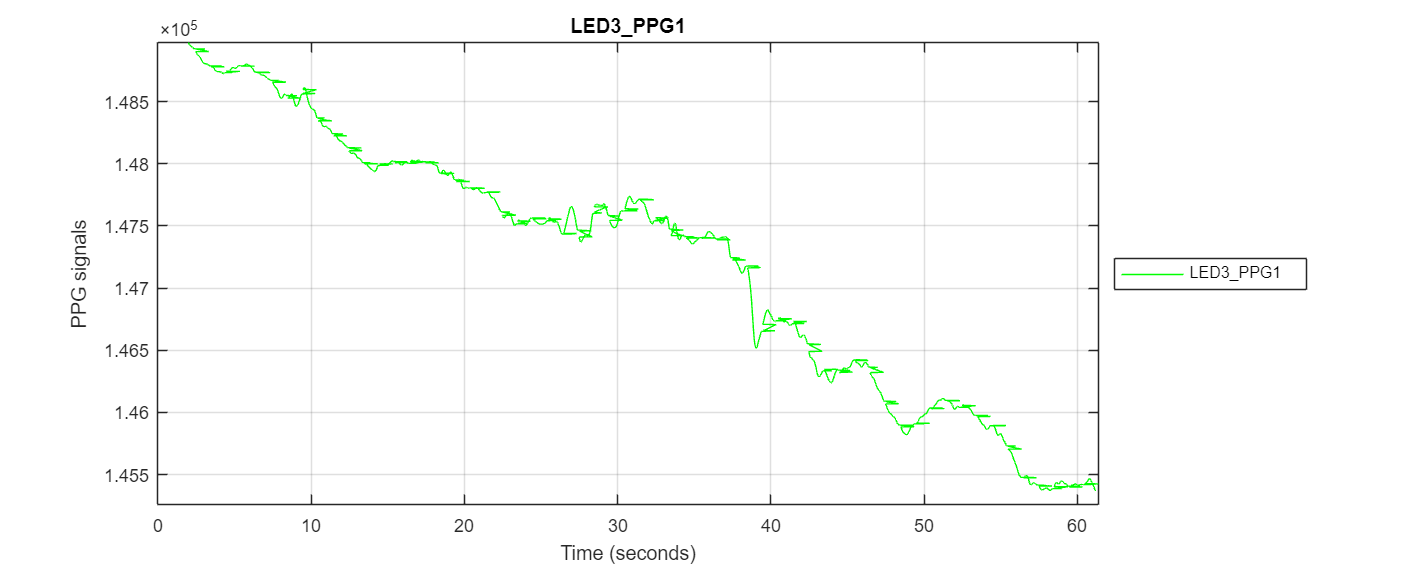

%  LED3_PPG1
figure;
set(gcf, 'Position', [100, 100, 2000, 800]);  % 
plot(time, data.LED3_PPG1, 'Color','#990000','LineWidth', 2 , 'DisplayName', 'LED3\_PPG1');
xlabel('Time (seconds)');
ylabel('PPG signals');
title('LED3\_PPG1');
xlim([0 max(time)])

% ylim([min_value_LED3 - padding_LED3, max_value_LED3 + padding_LED3]); %
grid on;
legend(Location="eastoutside");


exportgraphics(gcf, exportPath+"\PPG_LED3_data_for_experiment"+ experimentNumber +"_subject"+subject+".png", 'Resolution', 1000);

# Plot Accelerometer Data

% Plot accelerometer data
figure;
set(gcf, 'Position', [100, 100, 2000, 800]);  % [x, y, width, height]
hold on;
plot(time, data.ACC_X_mg_, 'r', 'LineWidth', 2, 'DisplayName', 'ACC_X');
plot(time, data.ACC_Y_mg_, 'g', 'LineWidth', 2, 'DisplayName', 'ACC_Y');
plot(time, data.ACC_Z_mg_, 'b', 'LineWidth', 2, 'DisplayName', 'ACC_Z');

xlabel('Time (seconds)');
ylabel('Acceleration (mg)');
title(accTitle);
legend(Location="eastoutside");
grid on;
hold off;

xlim([0 max(time)])
exportgraphics(gcf, exportPath+"\acc data for experiment"+ experimentNumber +" of subject"+subject+".png", 'Resolution', 1000);